# Project 1 by Quoc Nguyen (UHid: 1787501)

## Exercise 1

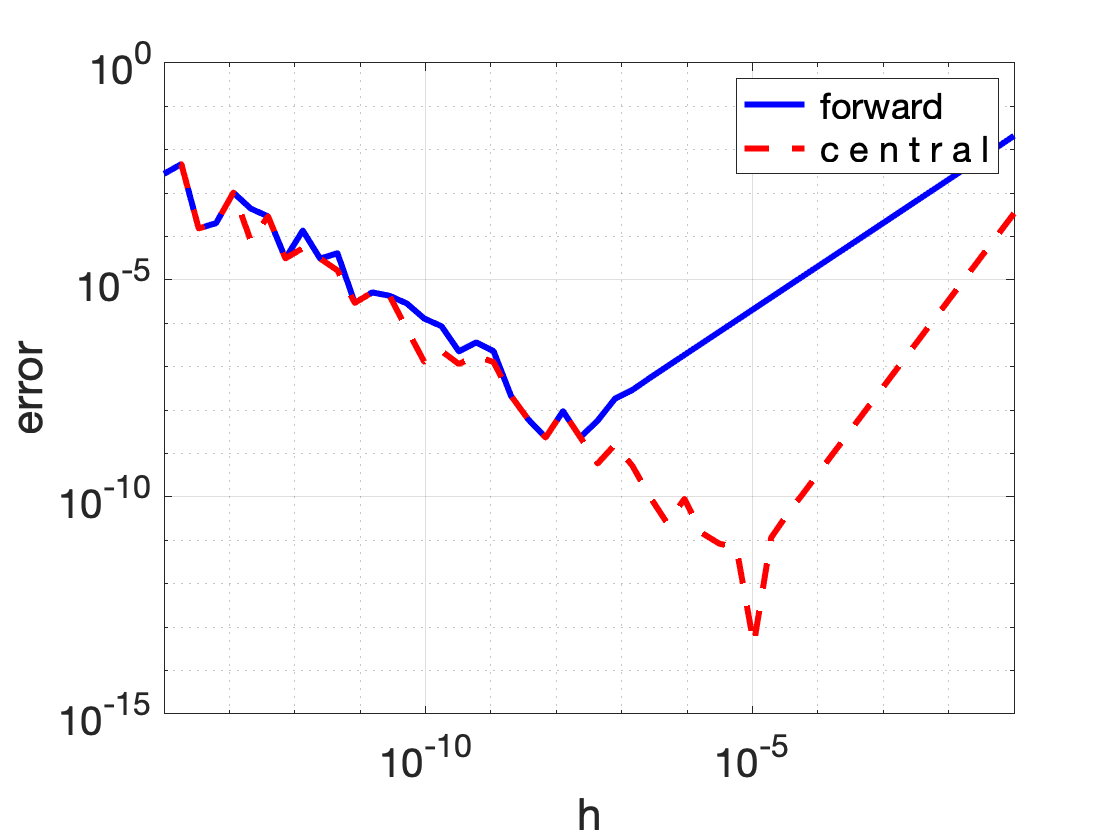

clear all ; close all ;
% create the step size vector
h = logspace(-1,-14,50);
x0 = 1; x1 = x0+h; xm1 = x0-h;
% the function values
y0 = exp(0.5*x0); y1 = exp(0.5*x1); ym1 = exp(0.5*xm1); % the true derivative
yDe = 0.5*exp(0.5*x0);
% the approximate derivatives
yDf = (y1-y0)./h;
yDfc = (y1-ym1)./(2*h);
% calculate the error
eDf = abs(yDf-yDe);
eDfc = abs(yDfc-yDe); %plot the error
loglog(h,eDf,'b-','LineWidth',3) ; hold on ; grid on ;
loglog( h , eDfc, 'r--', 'LineWidth',3) ; set(gca,'FontSize',20); xlabel('h'); ylabel('error'); legend ( ' forward ' , ' c e n t r a l ' ) ; xlim([min(h) max(h)]);

From the results, one can see that the error of the difference approximation decreases with respect to h, as long as h is above a certain threshold. In addition, the central difference approximation has a better convergence than the forward difference, which can be seen from the steeper slope of the corresponding line. 		

However, when h becomes too small, the difference between y(t) and y(t + h) becomes so small it cannot be evaluated accurately and significant bits are lost. In this case, rounding errors lead to a very inaccurate result which becomes even worse for smaller values of h. 

## Exercise 2

### a)  EULER is at the end of the file

### b) part 1

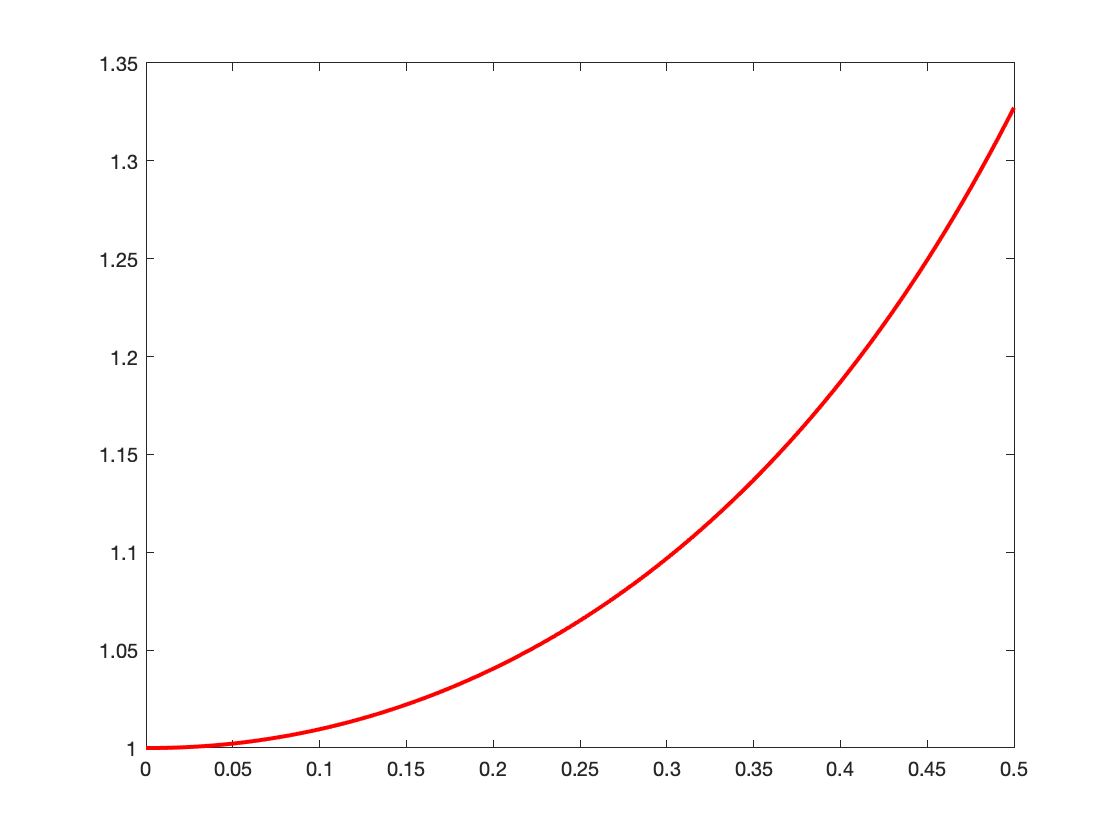

clear all; close all
t0 = 0;
y0 = 1;
n = 100;
var = '';
T=0.5;
% call the solver
[t,y] = EULER(@TESTFUNC,t0,T,y0,n,var);
% plot the output
plot(t ,y, 'r-' ,'LineWidth' , 2)

## b) part 2

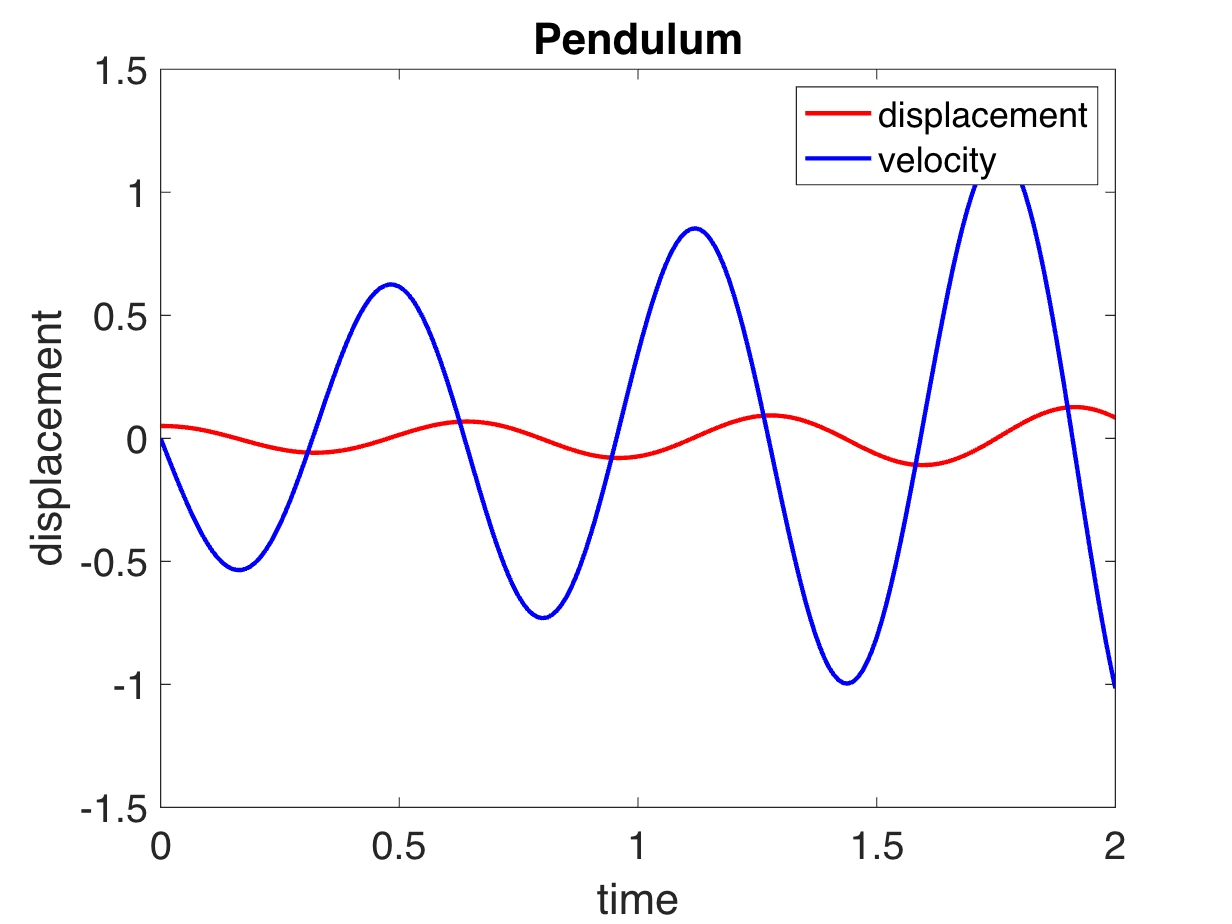

% clear all variables and plot windows
clear all; close all;

% set parameter
l = 0.1;       % length of pendulum
g = 9.81;    % gravitational constant

% write the variables into the field var
var = [l, g];

% set time interval
t0 = 0.0;
T = 2;

% initial conditions
x0 = [0.05; 0];
d = length(x0);

% number of time steps
n = 200;

% define the output variables
tvec = zeros(1,n+1);
xeuler = zeros(d,n+1);

% call the solvers
[tvec, xeuler] = EULER(@PENDULUMODE, t0, T, x0, n, var);

% create plot
figure(1);
title('Pendulum','FontSize',18);
hold on; box on;
xlabel('time','FontSize',18);
ylabel('displacement','FontSize',18);
set(gca,'FontSize',18);
hold on;
plot(tvec,xeuler(1,:),'r-','Linewidth',2);
plot(tvec,xeuler(2,:),'b-','Linewidth',2);
legend('displacement','velocity');
hold off

## Exercise 3


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
\mathrm{y1}\\
\mathrm{y2}\\
\mathrm{y3}\\
\mathrm{y4}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{y2}\\
\mathrm{y1}+2*\mathrm{y4}-\mu *\frac{\mathrm{y1}-\mu }{{\left({\left(\mathrm{y1}+\mu \right)}^2 +{\mathrm{y3}}^2 \right)}^{\frac{3}{2}} }-\mu *\frac{\mathrm{y1}-\mu^{\wedge } }{{\left({\left(\mathrm{y3}-\mu^{\wedge } \right)}^2 +{\mathrm{y3}}^2 \right)}^{\frac{3}{2}} }\\
\mathrm{y4}\\
\mathrm{y3}-2*\mathrm{y2}-\mu^{\wedge } *\frac{\mathrm{y3}}{{\left({\left(\mathrm{y1}+\mu \right)}^2 +{\mathrm{y1}}^2 \right)}^{\frac{3}{2}} }-\mu *\frac{\mathrm{y3}}{{\left({\left(\mathrm{y1}-\mu^{\wedge } \right)}^2 +{\mathrm{y3}}^2 \right)}^{\frac{3}{2}} }
\end{array}\right\rbrack$$


Write in a matrix form of first order

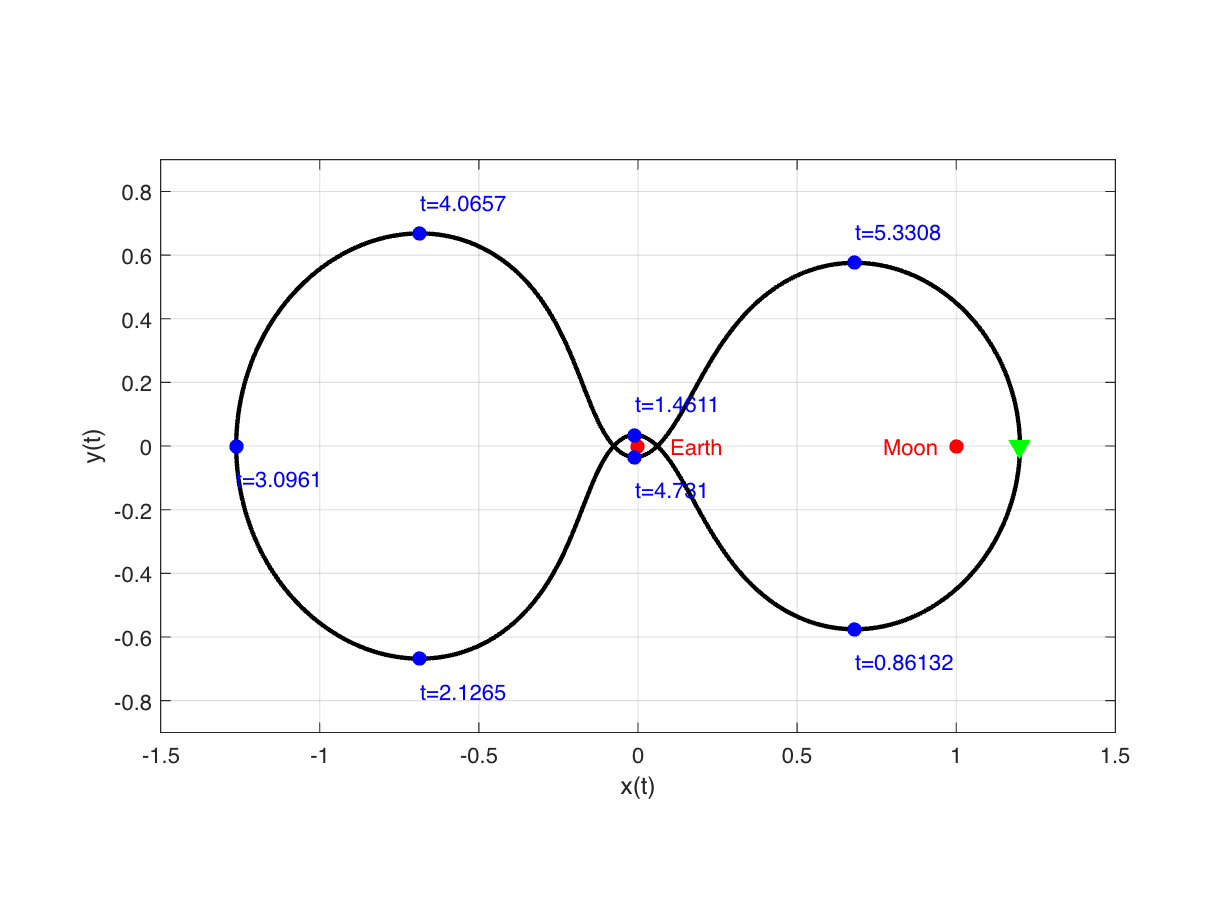

clear all; close all
%
% Satellite (restricted 3-body problem)
% 
% Illustrates the use of events and further options

% Integration interval, initial values
%
T = 6.19;
tspan = [0, T];
y0 = [1.2; 0; 0; -1.04935750983031990726];

% Calculation
%
options = odeset('RelTol',1e-7,'AbsTol',1e-8,'Events',@satevents);

[t,y,te,ye,ie] = ode45(@fSat,tspan,y0,options);

% Visualization
%
figure(1)
h1 = plot(y(:,1),y(:,2),'k-');
xlabel('x(t)')
ylabel('y(t)')
set(h1,'LineWidth',2);

hold on

plot(0,0,'ro','MarkerFaceColor','r'); text(0.1,0,'Earth','Color','r')
plot(1,0,'ro','MarkerFaceColor','r'); text(0.77,0,'Moon','Color','r')
plot(1.2,0,'gv','MarkerFaceColor','g','MarkerSize',8); 
plot(ye(:,1),ye(:,2),'bo','MarkerFaceColor','b');
for k=1:length(te)
   text(ye(k,1),ye(k,2)+0.1*sign(ye(k,2)),['t=' num2str(te(k))],'Color','b')
end
axis equal
axis([-1.5 1.5 -0.9 0.9])
grid on

hold off

## Exercise 3 part 2

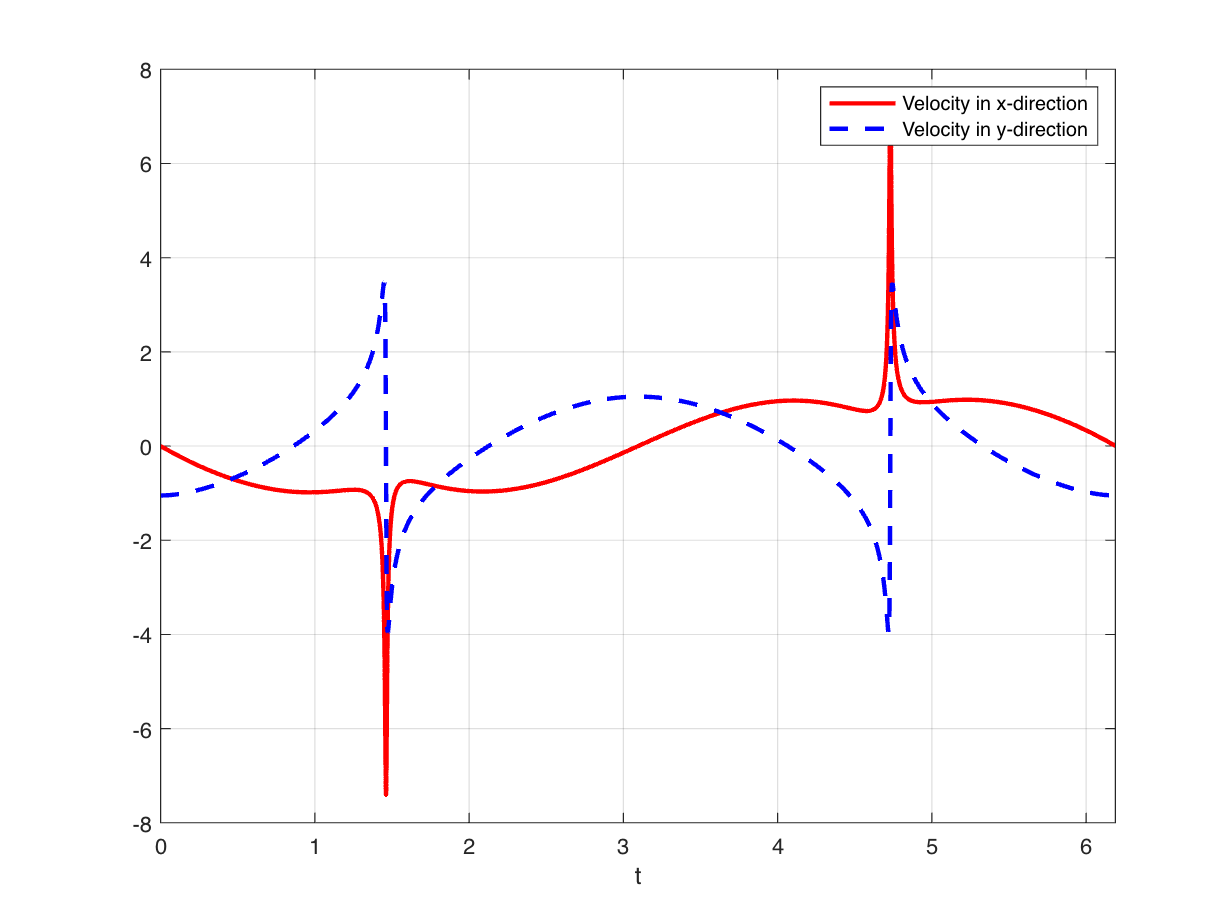


figure(2)
plot(t,y(:,3),'r','LineWidth',2);
hold on
plot(t,y(:,4),'b--','LineWidth',2)
xlabel('t')
legend('Velocity in x-direction','Velocity in y-direction')
grid on
axis([0 T -8 8])
hold off

## Exercise 4

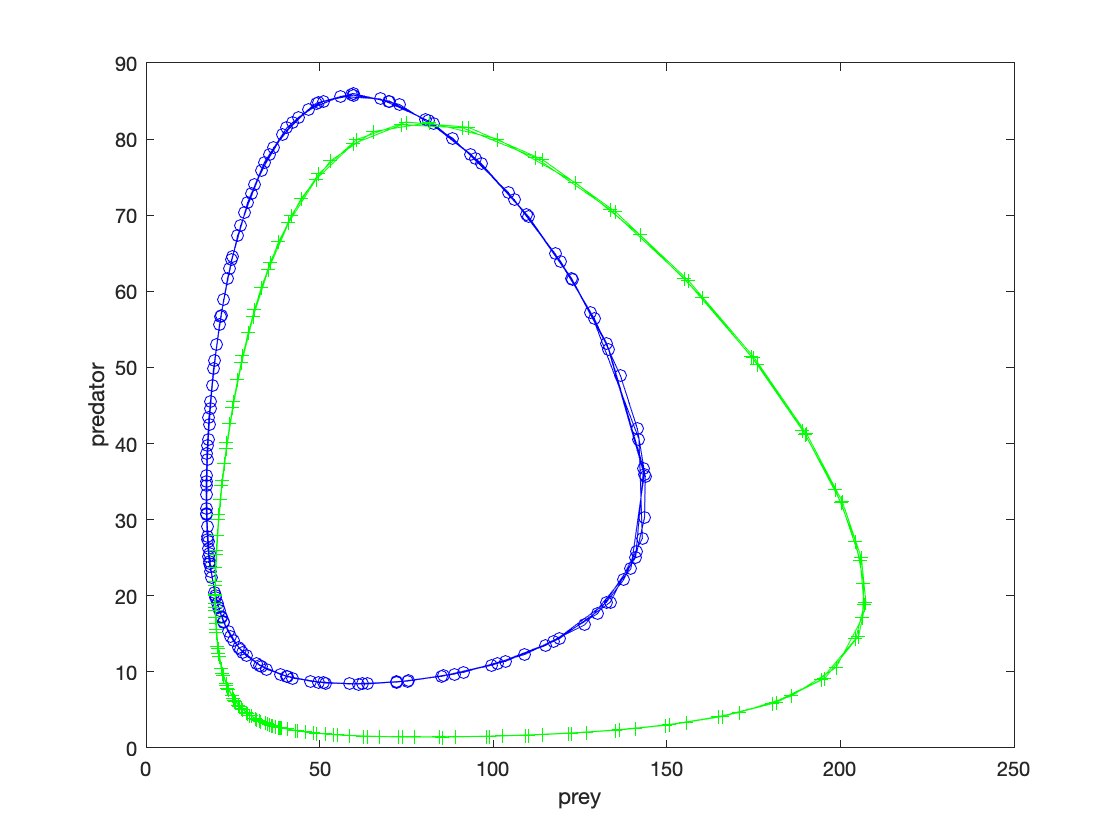

clear all, close all
% Solution of an IVP with MATLAB
% 
% The MATLAB ODE solver can be called by the following simple syntax:
% 
% [t,y] = solver(odefun,tspan,y0,options)
%
% Hereby, "solver" stands for one of the various solvers, for instance
% ode45, ode23, ode113 etc.
% 

% odefun stands for the definition of the right hand side of the
% differential equation, for instance in the predator-prey model the
% M-File withFishing.m or withoutFishing.m

% tspan specifies the integration interval, for instance

tspan = [0,25];

% y0 contains the initial values y(t=t_0) = y_0

y0 = [20; 20];

% The call of the solver is then as follows:

[t,y] = ode45('withoutFishing',tspan,y0);

plot(y(:,1),y(:,2),'b-o')
xlabel('prey')
ylabel('predator')

hold on

[t,y] = ode45('withFishing',tspan,y0);
plot(y(:,1),y(:,2),'g-+')

hold off

**Predator-Prey model of Volterra **


$$\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(a-e\right)*x\left(t\right)-b*x\left(t\right)*y\left(t\right)\\
-\left(c-e\right)*y\left(t\right)+d*x\left(t\right)*y\left(t\right)
\end{array}\right\rbrack$$


## Exercise 5

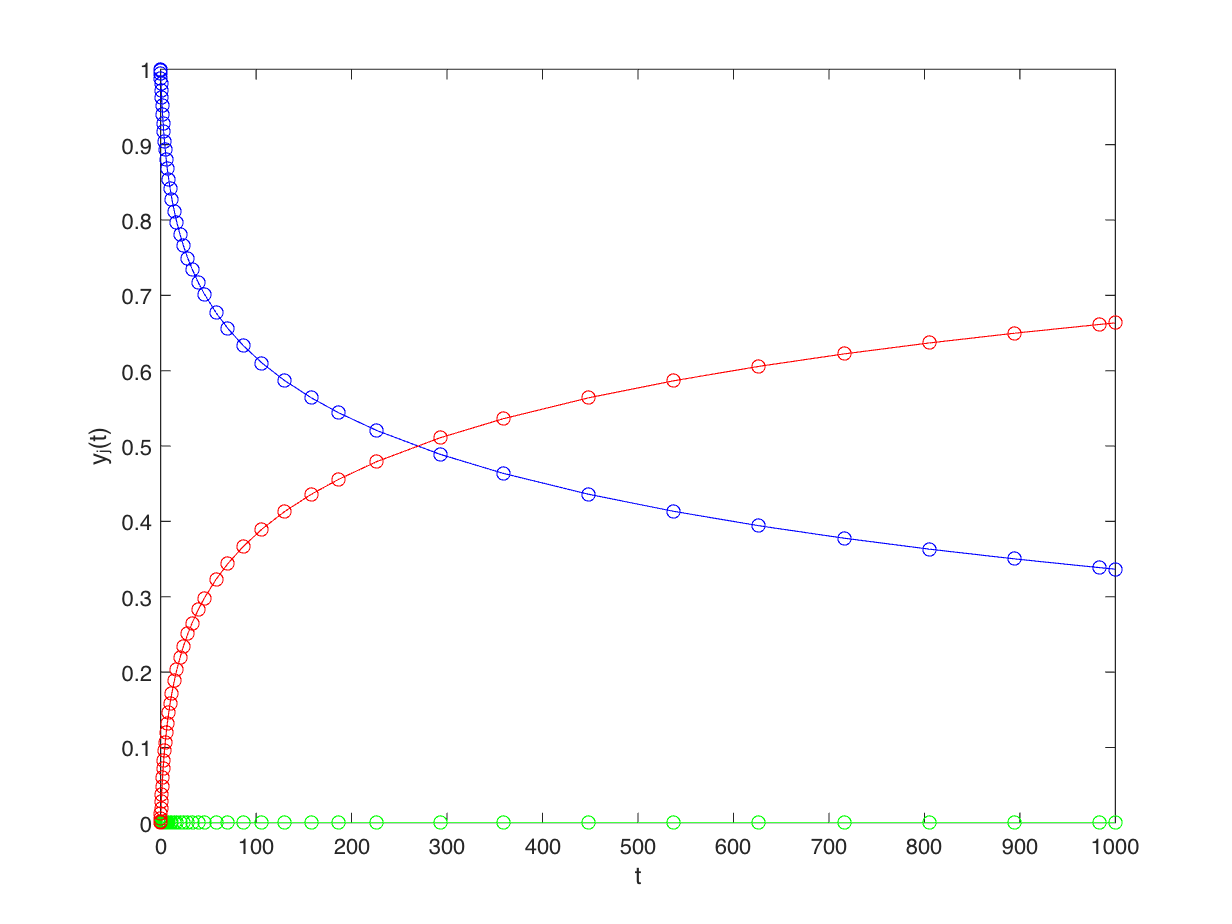



% Kinetics of an autocatalytic chemical reaction


% Parameters for the solver and call of the solver 
clear all; close all
tspan = [0, 1000];
y0 = [1; 0; 0];
[t,y] = ode23tb('chemistry',tspan,y0);

% Visualization
%
plot(t,y(:,1),'b-o')
xlabel('t')
ylabel('y_j(t)')

hold on

plot(t,y(:,2),'g-o')
plot(t,y(:,3),'r-o')

hold off	

**Autocatalytic chemical reaction **


$$\frac{\textrm{d}}{\textrm{d}t}\left\lbrack \begin{array}{c}
\mathrm{y1}\\
\mathrm{y2}\\
\mathrm{y3}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\mathrm{k1}*\mathrm{y1}+\mathrm{k2}*\mathrm{y2}*\mathrm{y3}\\
\mathrm{k1}*\mathrm{y1}-\mathrm{k2}*\mathrm{y2}*\mathrm{y3}-*\mathrm{k3}*{\left(\mathrm{y2}\right)}^2 \\
\mathrm{k3}*{\left(\mathrm{y2}\right)}^2 
\end{array}\right\rbrack$$


# Function

#### Exercise 2

function [t,y] =EULER(FUNC,t0,T,y0,n,var)
    t(1) = t0; y(:,1) = y0; h = (T-t0)/n;
    for i = 1:n
    t(i+1) = t0 + i*h;
    y(:,i+1) = y(:,i) + h*FUNC(t(i),y(:,i), var);
    end
end


function [f] =TESTFUNC(t,y, var);
    f = 2*t*y.^2;
end

function [f] =PENDULUMODE(t,y,var)

    l = var(1);
    g = var(2);
f = [y(2); -g/l*sin(y(1))];
end

#### Excercise 3

function f = fSat(t,y)
%
% right hand side for the satellite example

mu = 1/82.45;
mup = 1-mu;

f(1) = y(3);
f(2) = y(4);
f(3) = y(1) + 2*y(4) ...
	    - mup * (y(1)+mu ) / (((y(1)+mu )^2+y(2)^2)^(3/2)) ...
        - mu  * (y(1)-mup) / (((y(1)-mup)^2+y(2)^2)^(3/2));
f(4) = y(2) - 2*y(3) ...
	    - mup * y(2) / (((y(1)+mu )^2+y(2)^2)^(3/2))...
        - mu  * y(2) / (((y(1)-mup)^2+y(2)^2)^(3/2));
	
f = f';
end

function [value,isterminal,direction] = satevents(t,y)
%
% File with event functions for satellite problem

    value = [y(3); y(4)];
    isterminal = [0; 0];            
    direction = [1; 0];            
 
end


#### Excercise 4

function dydt = withoutFishing(t,y)

    a = 1; 
    b = 0.03;
    c = 1.2;
    d = 0.02;
    e = 0;

    dydt = [(a-e - b*y(2))*y(1);
        (-(c+e) + d*y(1))*y(2)];
end

function dydt = withFishing(t,y)

    a = 1; 
    b = 0.03;
    c = 1.2;
    d = 0.02;
    e = 0.4;

    dydt = [(a-e - b*y(2))*y(1);
        (-(c+e) + d*y(1))*y(2)];
end


#### Exercise 5

function dydt = chemie(t,y)
%
% Kinetics of an autocatalytic chemical reaction

% This function provides the right hand side of the differential equation 
% the MATLAB ODE solver .
%
% 
k1 = 0.04;
k2 = 1e4;
k3 = 3e7;

dydt = [ -k1*y(1) + k2*y(2)*y(3);
          k1*y(1) - k2*y(2)*y(3) - k3*y(2)*y(2);
		                           k3*y(2)*y(2)];
end
